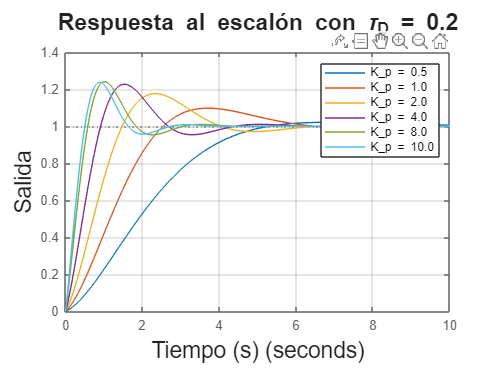

close all;
clear;
clc;

% Parámetros del sistema
K = 1;
p = 1;
t = 0:0.01:10;

%% Gráfica 1: tau_D fijo, Kp variable
tauD_fixed = 0.2;
Kp_vals = [0.5, 1, 2, 4, 8, 10];

fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);  % Tamaño físico
hold on;
for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);
    num = (Kp * K)*[tauD_fixed, 1];
    den = [1, (p + Kp * K * tauD_fixed), Kp * K];
    sys = tf(num, den);
    step(sys, t);
end
title(['Respuesta al escalón con \tau_D = ' num2str(tauD_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(k) sprintf('K_p = %.1f', k), Kp_vals, 'UniformOutput', false));
grid on;
% set(gca, 'FontSize', 13);
print(fig1, 'salidaKpconst2', '-dpdf', '-r300');  % o usa exportgraphics

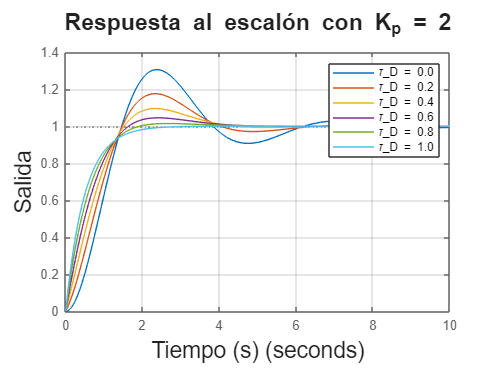



%% Gráfica 2: Kp fijo, tau_D variable
Kp_fixed = 2;
tauD_vals = [0, 0.2, 0.4, 0.6, 0.8, 1.0];

fig2 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);
hold on;
for i = 1:length(tauD_vals)
    tauD = tauD_vals(i);
    num = Kp_fixed * K*[tauD, 1]; 
    den = [1, (p + Kp_fixed * K * tauD), Kp_fixed * K];
    sys = tf(num, den);
    step(sys, t);
end
title(['Respuesta al escalón con K_p = ' num2str(Kp_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(t) sprintf('\\tau_D = %.1f', t), tauD_vals, 'UniformOutput', false));
grid on;

% Evita DIN A4 y recorte
set(fig2, 'PaperUnits', 'centimeters');
set(fig2, 'PaperSize', [20 15]);
set(fig2, 'PaperPosition', [0 0 20 15]);

print(fig2, 'salidataucnst2', '-dpdf', '-r300');

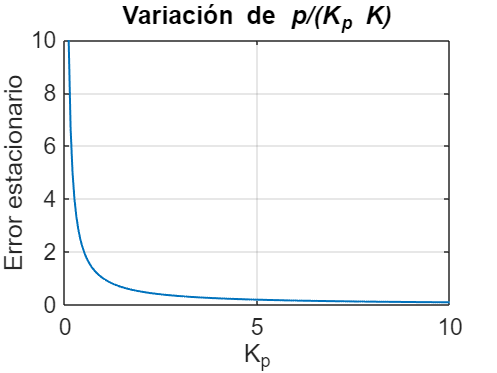

  p = 1;
    K = 1;

    % Rango de Kp
    Kp = linspace(0.1, 10, 200);  % evitar división por cero

    % Cálculo de la expresión
    error = p ./ (Kp * K);

    % Graficar
    fig3 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);
    plot(Kp, error, 'LineWidth', 1.5);
    title('Variación de \it{p}/(K_p K)', 'FontSize', 17);
    xlabel('K_p', 'FontSize', 17);
    ylabel('Error estacionario', 'FontSize', 17);
    grid on;
    set(gca, 'FontSize', 17);
print(fig3, 'errorPD', '-dpdf', '-r300');